# Example 3: Design of Experiments using TPMS

This example outlines the process for generating a full factorial design of experiments, by first defining the structure and levels.

First, cleanup and set up the paths for any data, results and filenames.

Also decide what results we want to save (save out stl files for additive manufacture, or 2D screenshots for reporting/analysis purposes).

studyName = "CellSize"; 
dataPath = 'data\';
saveFigures = 0;
saveSTL = 0;

if saveFigures||saveSTL
    resultPath = "result\"+studyName+"\";
    if ~isfolder("result\"+studyName)
        mkdir("result\",studyName);
    end
    addpath(resultPath);
end
warning('off','all');

## Set up the design variables

Here the variables which parametrically describe the TPMS-like structure are defined.

The **equation** of the tpms, **type** of structure, nodes per unit cell edge (**res**), and isovalues (**v**) define the fundamental structure form and discretisation. 

Alternatively the user my specify a target volume fraction (**vf**) in palce of the primary isovalue (**v1**).

DOE.res = [30]; % Resolution (nodes per cell)
DOE.vf = [0.5]; % alternative definition of volume fraction 
DOE.equation = ["Gyroid"];% "Gyroid","Diamond","Primative", "Neovius", "IWP", "FRD"
DOE.type = ["network"];% "network","double","surface"

A set of parametric affine transformations are defined using Cell Size (**ax**,**ay**,**az**) in mm, Offsets or phase shift (**ox**,**oy**,**oz**) in mm and finally euler rotations defined by **pitch**,**roll **and** yaw** in degrees.

DOE.ax = [10]; % Cell size: x,y,z (mm)
DOE.nx = [1]; %DOE.ny = 1; DOE.nz = 1; % Define number of cells
DOE.ox = [0 pi/4 pi/2 3*pi/4]; %DOE.oy = [0]; DOE.oz = [0]; % Offsets: x,y,z
DOE.pitch = [0]; DOE.roll = [0]; DOE.yaw = [0]; % Rotations: pitch,roll,yaw (deg)

## Generate the DOE as a structure

Next we need to automatically set up the full-factorial design of experiments, including sample names.

Note that any values not set will default to a generally "safe" value when generating the structures.

names = string(fieldnames(DOE));
levels = zeros(length(names),1);
for i = 1:length(names)
    levels(i) = length(DOE.(names(i)));
end

doeFF = fullfact(levels);
doeArray = struct();

for i = 1:size(doeFF,1)
    for j = 1:size(names,1)
        doeArray(i,1).(names(j)) = DOE.(names(j))(doeFF(i,j));
    end
    % Create a name for the sample - you may wish to change this to show
    % more data
    doeArray(i,1).name = studyName+" "+num2str(i,'%4.0f');
end

## Run the different designs

Set up the for loop to run each design. You may want to specify the level of analysis - (remembering mechanical, curvature, trimesh will all add computational cost and time to every model).

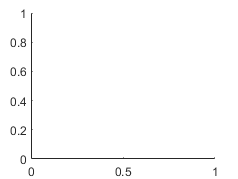

calculatefields = 1;
calculatemechanical = 0;
calculatetrimesh = 1;
curvaturemethod = 'none'; %Select 'patch', 'implicit', 'trimesh' or 'none'.

f = figure; ax = gca; % Figure and axis handles

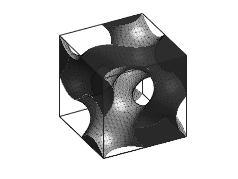

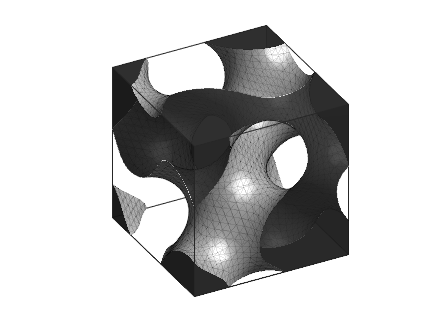

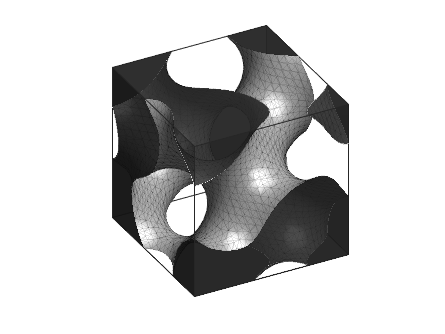

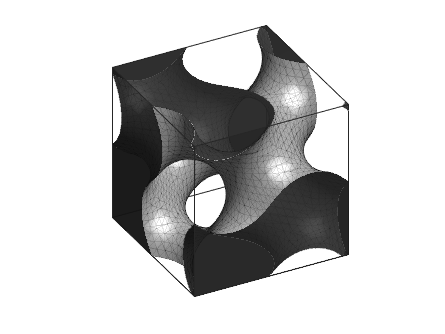


for i = 1:size(doeArray,1)
    d = doeArray(i);
    %TPMS(equation,type,v,vf,res,cellSize,ncells,Rxyz,offset)
    tpms = TPMS(d.equation,d.type,[],d.vf,[d.res,d.res,d.res],[d.ax,d.ax,d.ax],[d.nx,d.nx,d.nx],...
        [d.pitch,d.roll,d.yaw],[d.ox,d.ox,d.ox]);
    % Run full analysis - select (fields,mechanical,trimesh,curvature)
    tpms = tpms.properties(calculatefields,calculatemechanical,calculatetrimesh,curvaturemethod);
    
    % Export the metrics results and display the computational time
    DOEout(i,:) = [table(d.name) struct2table(tpms.export,'AsArray',true)];
    
    % Preview the structure
    opts.fancy = 1;
    figure; ax= gca;
    tpms.plot(ax,'trimesh','none',[],opts);
    axis(ax,[0 d.ax.*d.nx 0 d.ax.*d.nx 0 d.ax.*d.nx]);
    ax.Box = 'on';
    ax.BoxStyle = 'full';
    Message = sprintf('Structure %5.0f of %5.0f',i,size(doeArray,1));
    %title(ax,Message);    
    % Save figures as .png files in the results folder
    if saveFigures
        fid = strcat(resultPath,d.name,".png");
        saveas(f,fid,'png');
    end
    
    % Save mesh as .stl files in the results folder
    if saveSTL
        fid = strcat(resultPath,d.name,".stl");
        stlwrite(tpms.FV,fid)
    end
    
    pause(0.01);
end

# Post Processing the DOE results

## Set up the properties to plot (X vs Y scatterplots, with surface type grouping)

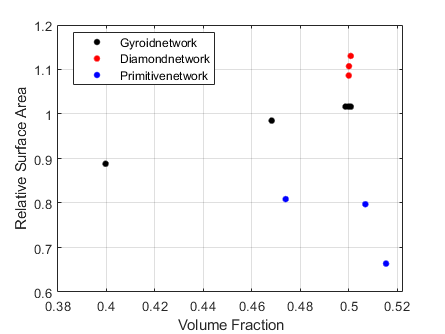

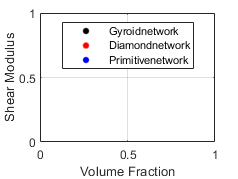

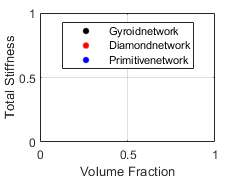

Yvars = ["relativeArea", "elastic", "poisson", "zenerRatio", "shear", "totalStiffness"];
plotlabels = ["Relative Surface Area", "Elastic Modulus", "Poisson Ratio", "Zener Anisotropy Ratio", "Shear Modulus", "Total Stiffness"];
Xvar = "volumeFraction";
grouping = strcat(DOEout.equation, DOEout.type);
% Set the datapoint colors and symbols
colors = [0 0 0; 1 0 0; 0 0 1;0 0 0; 1 0 0; 0 0 1];
sym = '...xxx';

%Make the plots
for i=1:length(Yvars)
    f = figure;
    ax = gca;
    L = gscatter(ax,DOEout.(Xvar),DOEout.(Yvars(i)),grouping,colors,sym);
    hold on;
    xlabel('Volume Fraction');
    ylabel(plotlabels(i));
    grid on;
end

## Do analysis on the design of experiments

% List of variables to plot main effects of
Yvars = ["CPUtime","Nfaces","Nnodes","volume","surfaceArea","volumeFraction","relativeArea","rmsMC","thickness","poreDiameter","areaVar","areaMean","areaStd","areaBelow30deg","LpbfRa_Max", ...
  "LpbfRa_Mean", "LPBFerror_Max","LPBFerror_Mean", "elastic", "poisson","shear", "totalStiffness","zenerRatio"];

for i = 1:length(Yvars)
    figure
    maineffectsplot(DOEout.(Yvars(i)),doeFF,'varnames',names);
    title(Yvars(i));
end

Error using maineffectsplot (line 106)
GROUP must be a cell array or matrix of grouping variables with the same length as Y.


%plotmatrix(DOEout(:,Yvars));